# Exercicis

## Exercici 1

Calculeu l'histograma dels angles dels gradients d'una imatge (100x100  píxels) generada sintèticament que consisteixi en un degradat de grisos  amb origen el centre de la imatge i amb forma de 'flam' gaussià (Two-dimensional Gaussian function).

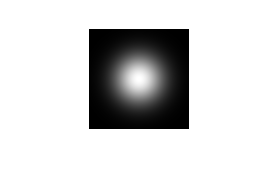

N = 100;
I = fspecial("gaussian", N, N/6);
imshow(I,[]);

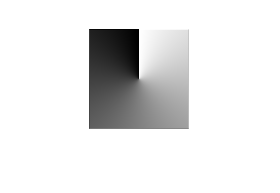

% sobel
hx = [1 0 -1; 2 0 -2; 1 0 -1];
Gx = imfilter(double(I), hx);
hy = hx';
Gy = imfilter(double(I), hy);
Angle = 180*(atan2(Gx, Gy) + pi)/pi;
imshow(Angle,[]);

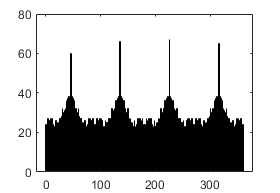

H = histogram(Angle,360);

## Exercici 2

 Es vol tenir una útil aplicació de visió per computador que ajudi a trobar a Odlaw, utilitzant el coneixement que la samarreta d’Odlaw està composta de franges negres i grogues. Amb aquest objectiu, caldrà crear una imatge que sigui una mena de mapa tèrmic; que indiqui on les franges negres i grogues (amb prou gruix) es troben. Elimineu les deteccions espúries (petites deteccions) i feu una superposició del mapa tèrmic (en vermell) amb la imatge original (en gris).

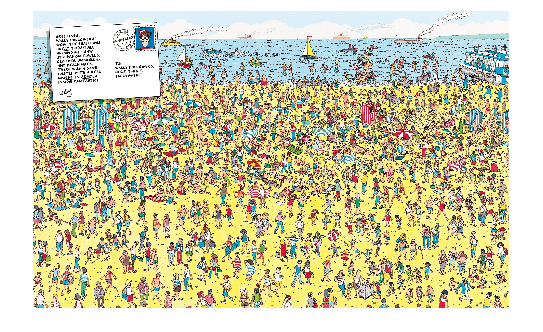

I = imread('wally.jpg');
imshow(I);

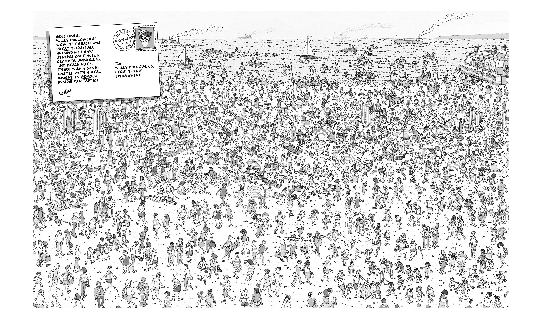

HSV = rgb2hsv(I);

% Color negre
Black = HSV(:,:, 3);
imshow(Black);

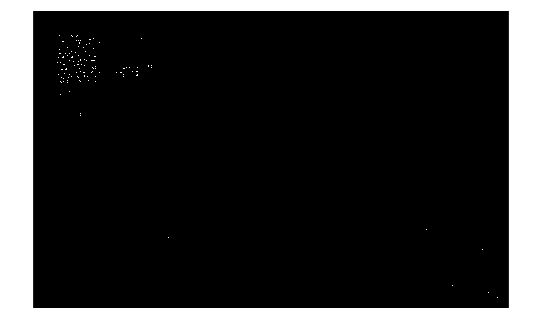

B = Black < 0.15;
ES = [1,1,1,1,1; 1,1,1,1,1; 1,1,1,1,1];
B = imerode(B,ES);
ES = strel('disk', 2);
B = imdilate(B,ES);
imshow(B);

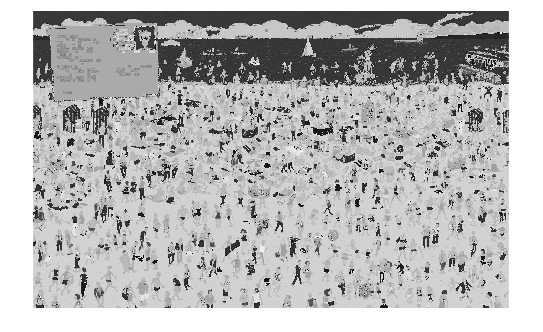


% Color groc
Yellow = mod(HSV(:,:,1)+4/6, 1);
imshow(Yellow);

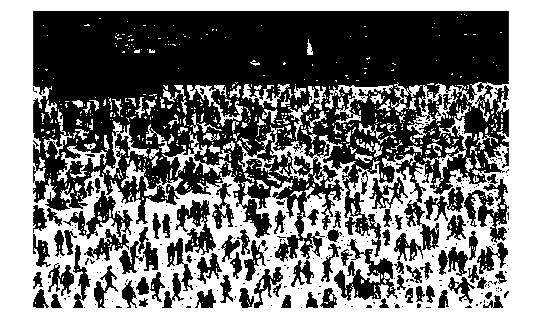

Y = Yellow > 0.80;
ES = [1,1,1,1,1; 1,1,1,1,1; 1,1,1,1,1];
Y = imerode(Y,ES);
ES = strel('disk', 2);
Y = imdilate(Y,ES);
imshow(Y);

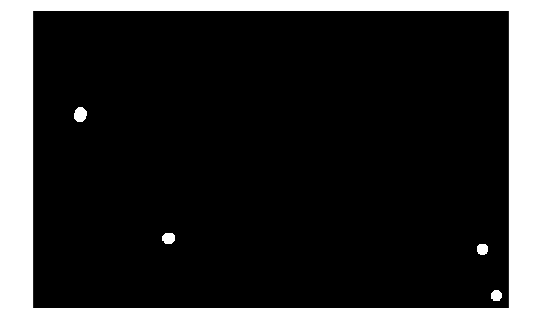


% and
A = B&Y;
ES = strel('disk', 30);
A = imdilate(A,ES);
imshow(A);

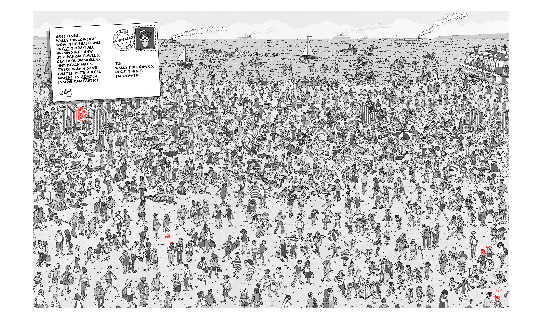


% pintar fotografia
G = rgb2gray(I);
RGB(:,:,1) = G;
RGB(:,:,2) = G;
RGB(:,:,3) = G;
RGB(:,:,1) = max(uint8(255*A), RGB(:,:,1));
imshow(RGB);